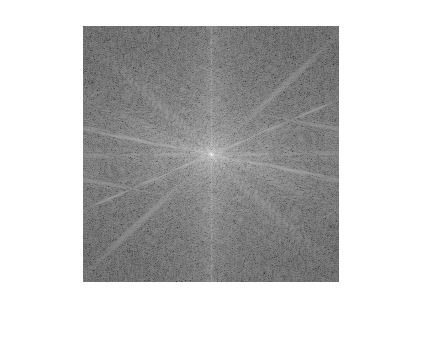

cam = imread("cameraman.tif");
sf = fftshift(fft2(cam));

fftshow(sf,'log');

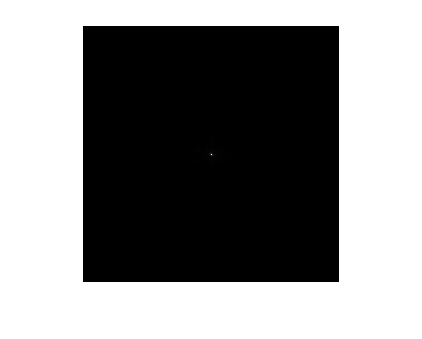

fftshow(sf,'abs');

imshow(cam);

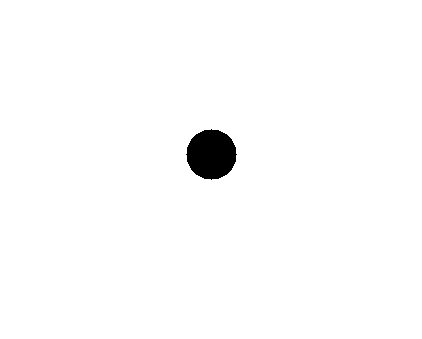

[x y] = meshgrid(-128:127,-128:127);
z= sqrt(x.^2 +y.^2);

circle= (z>25);

imshow(circle);

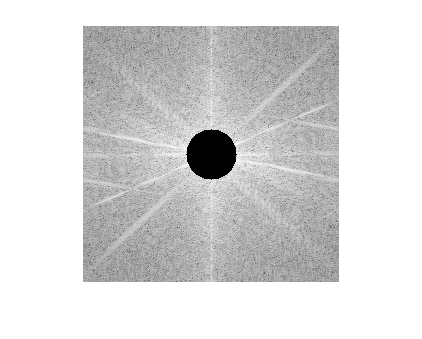


mutli = sf .* circle;

fftshow(mutli);

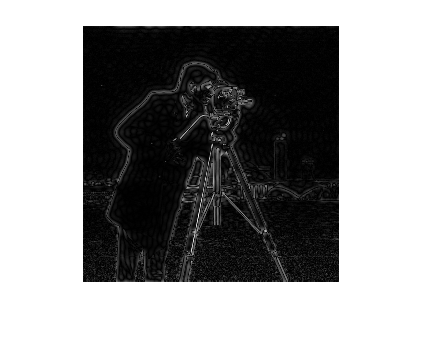

inverse_multi = ifft2(mutli);

fftshow(inverse_multi,'abs');

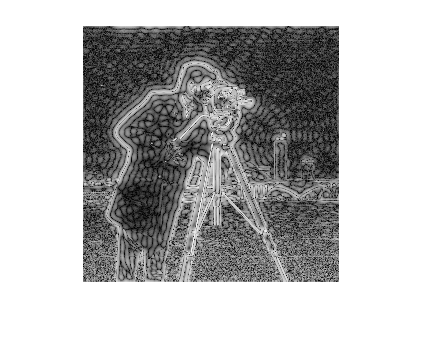

fftshow(inverse_multi,'log');

Effect of LPF on my image

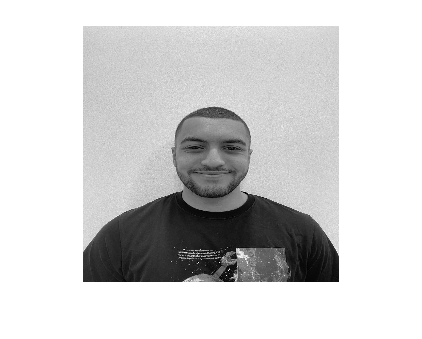

me = imread("megray.tif");
sf_me = fftshift(fft2(me));

imshow(me);

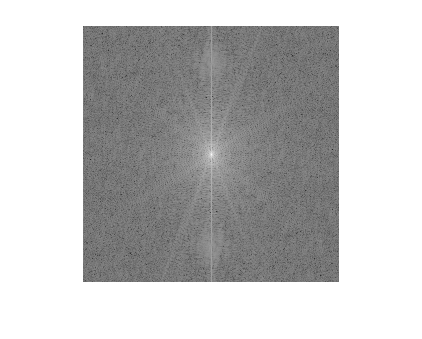

fftshow(sf_me,'log');

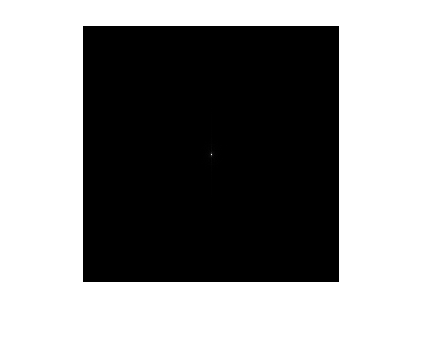

fftshow(sf_me,'abs');

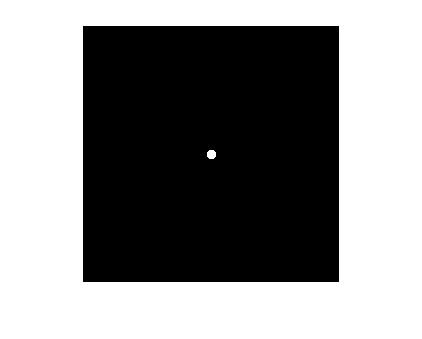


[x y] = meshgrid(-128:127,-128:127);
z= sqrt(x.^2 +y.^2);
%%% Circle diameter 5
circle_LPF= (z<5);

imshow(circle_LPF);

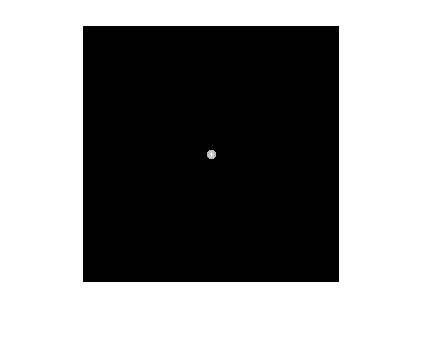


mutli = sf_me .* circle_LPF;

fftshow(mutli);

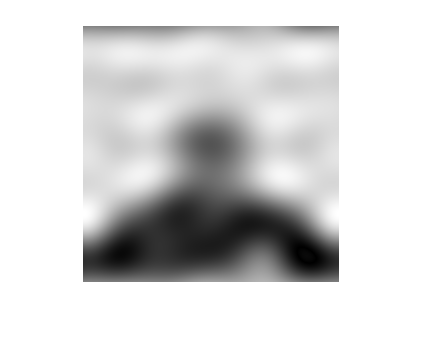


inverse_multi = ifft2(mutli);

fftshow(inverse_multi,'abs');

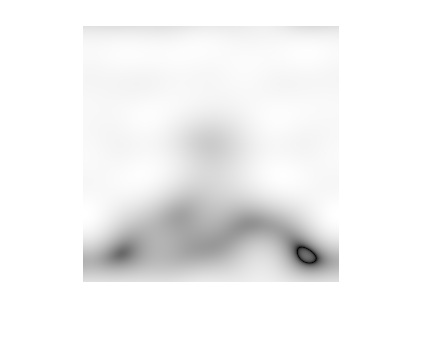

fftshow(inverse_multi,'log');

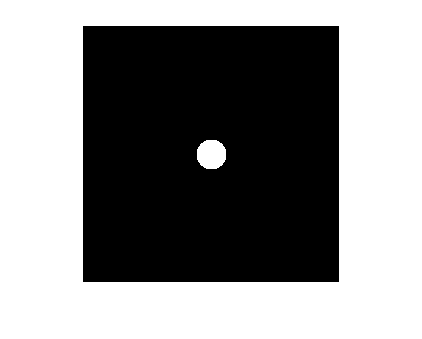

%%% Circle diameter 15
circle_LPF= (z<15);

imshow(circle_LPF);

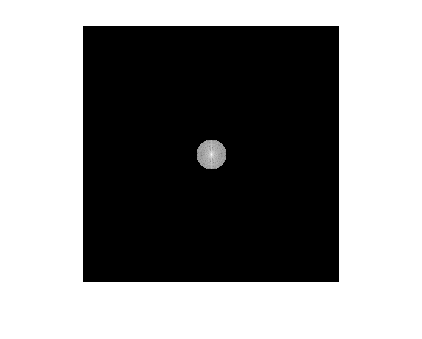


mutli = sf_me .* circle_LPF;

fftshow(mutli);

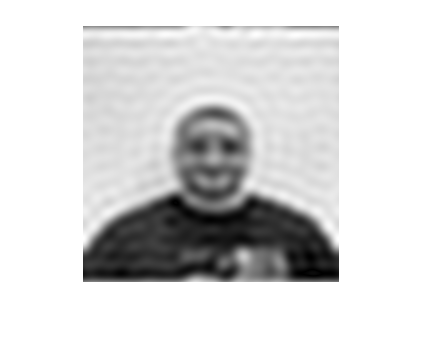


inverse_multi = ifft2(mutli);

fftshow(inverse_multi,'abs');

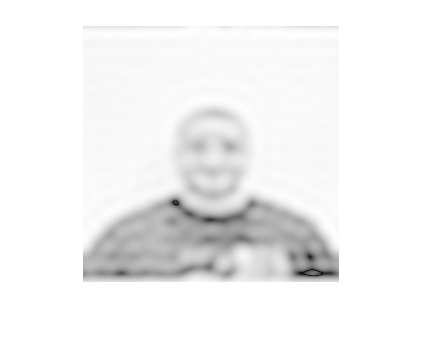

fftshow(inverse_multi,'log');

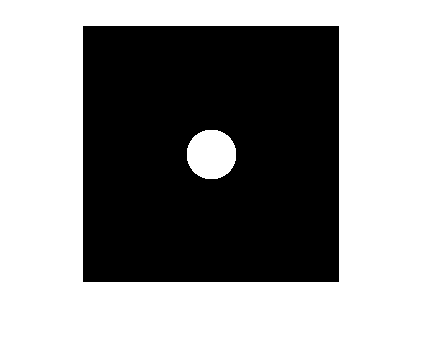

%%% Circle diameter 25
circle_LPF= (z<25);

imshow(circle_LPF);

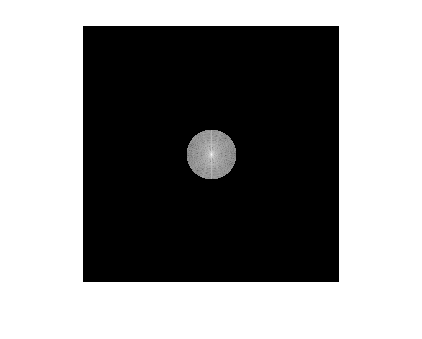


mutli = sf_me .* circle_LPF;

fftshow(mutli);

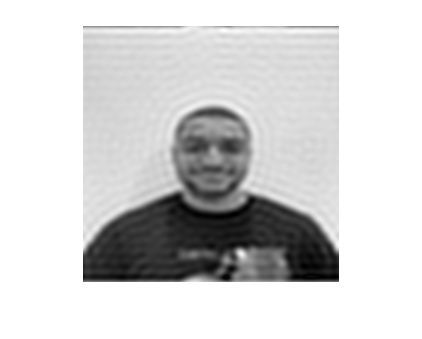


inverse_multi = ifft2(mutli);

fftshow(inverse_multi,'abs');

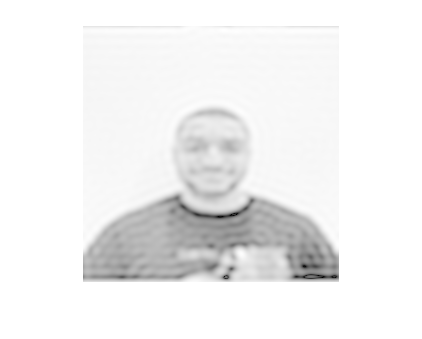

fftshow(inverse_multi,'log');

Effect of HPF on my image

me = imread("megray.tif");
sf_me = fftshift(fft2(me));

imshow(me);

fftshow(sf_me,'log');

fftshow(sf_me,'abs');

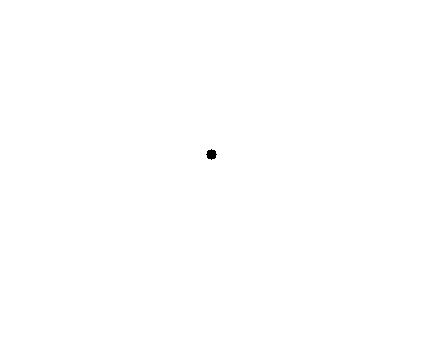


[x y] = meshgrid(-128:127,-128:127);
z= sqrt(x.^2 +y.^2);
%%% Circle diameter 5
circle_HPF= (z>5);

imshow(circle_HPF);

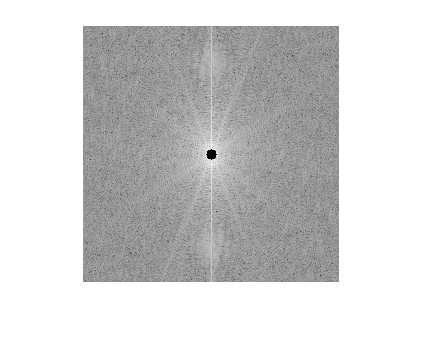


mutli = sf_me .* circle_HPF;

fftshow(mutli);

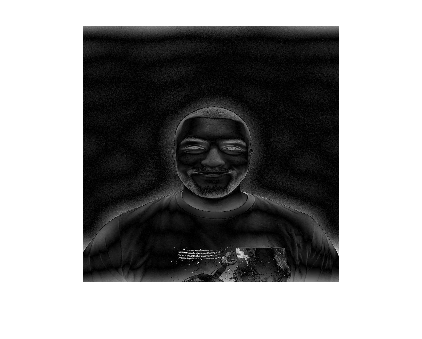


inverse_multi = ifft2(mutli);

fftshow(inverse_multi,'abs');

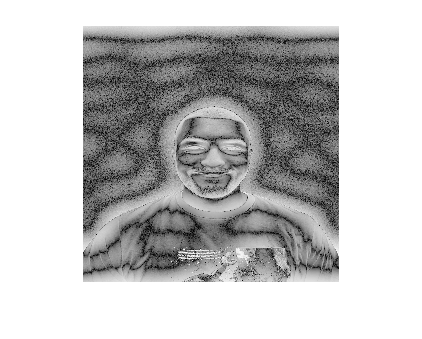

fftshow(inverse_multi,'log');

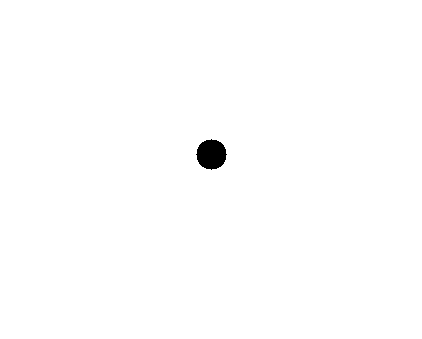

%%% Circle diameter 15
circle_HPF= (z>15);

imshow(circle_HPF);

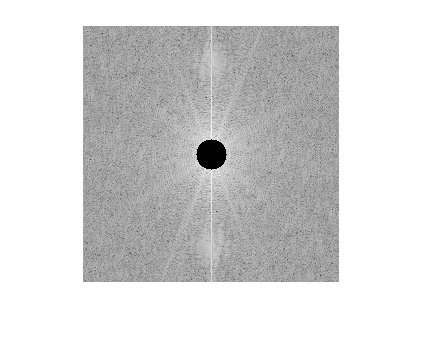


mutli = sf_me .* circle_HPF;

fftshow(mutli);

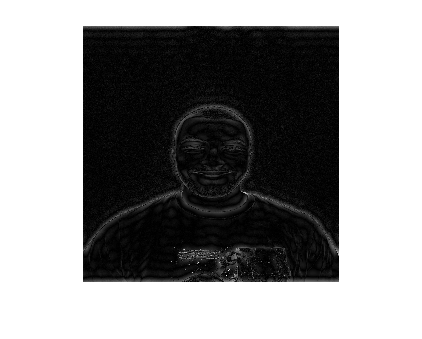


inverse_multi = ifft2(mutli);

fftshow(inverse_multi,'abs');

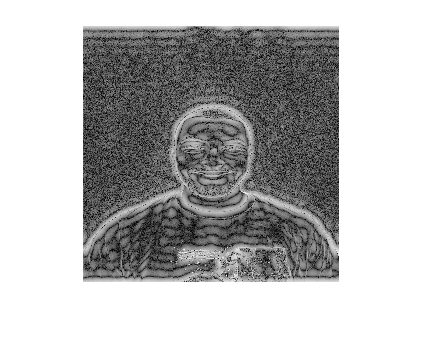

fftshow(inverse_multi,'log');

%%% Circle diameter 25
circle_HPF= (z>25);

imshow(circle_HPF);

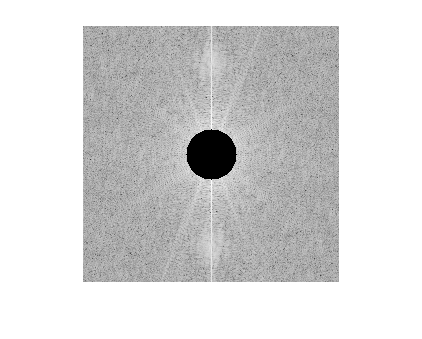


mutli = sf_me .* circle_HPF;

fftshow(mutli);

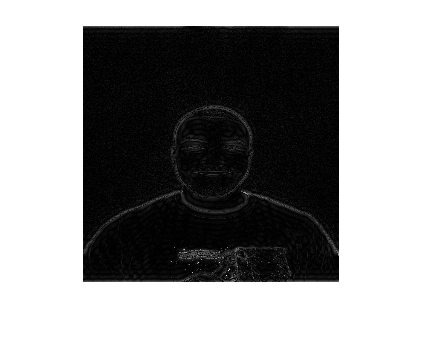


inverse_multi = ifft2(mutli);

fftshow(inverse_multi,'abs');

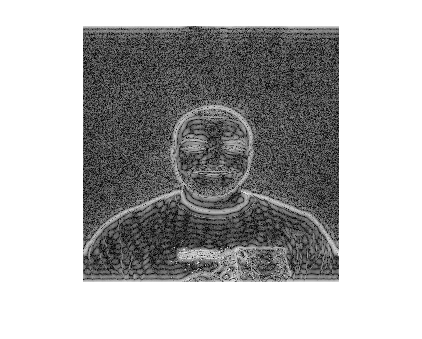

fftshow(inverse_multi,'log');

Butter forth filters (downloaded on images folder)

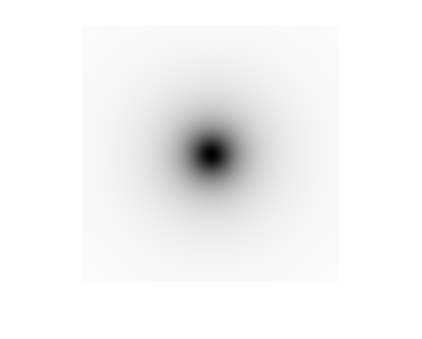

butterH = hbutter(me,15,1);
imshow(butterH);

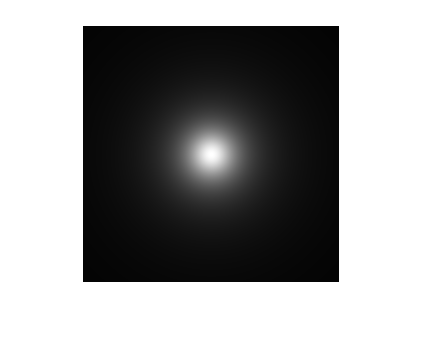


butterL = lbutter(me,15,1);
imshow(butterL);

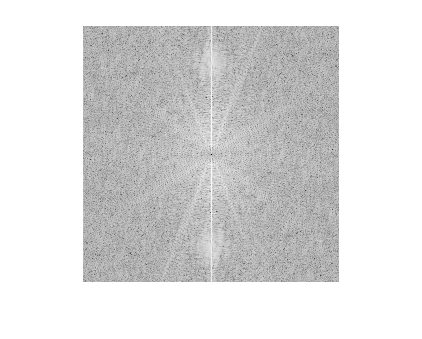

%% HPF
mutli = sf_me .* butterH;

fftshow(mutli);

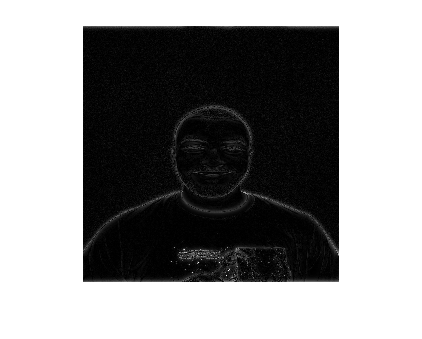


inverse_multi = ifft2(mutli);

fftshow(inverse_multi,'abs');

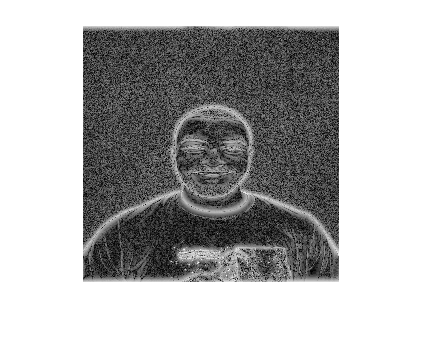

fftshow(inverse_multi,'log');

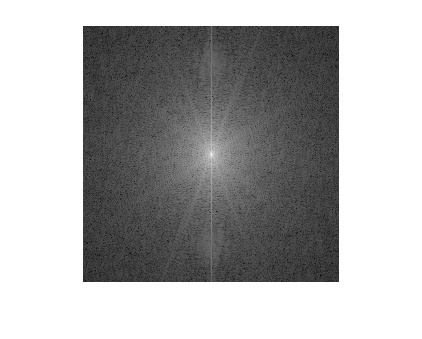


%% LPF
mutli = sf_me .* butterL;

fftshow(mutli);

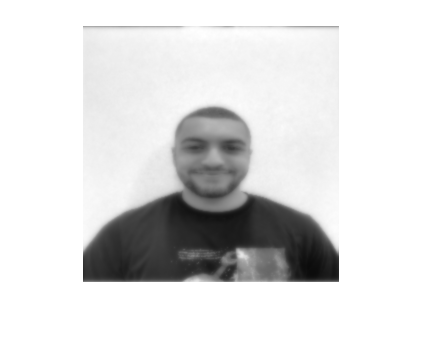


inverse_multi = ifft2(mutli);

fftshow(inverse_multi,'abs');

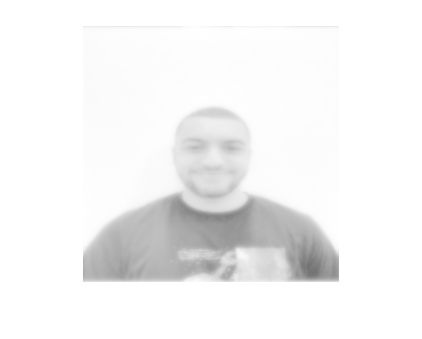

fftshow(inverse_multi,'log');